# Importing DATA

clear all; clc; 
format long g;
sensor_data= readmatrix('fort600.xlsx');
% sensordata = dlarray(sensor_data);
sensordata = sensor_data(1:1600,1:24);% To get 1600 points
% Data_in = sensordata(1,1:8);      
% Data_in = [Data_in;sensordata(1,9:16)]
% Data_in = [Data_in; sensordata(1,17:24)]
% for i = 1:1597
%     Data_in = [Data_in; sensordata(i,25:32)];
% end
data = sensordata';
dataN = data;% noisy data
num_data = 1600;

## loading the noise free data

nfreemat = readmatrix('nfree-train.xlsx');
data_nfree = nfreemat(1,1:8);
data_nfree = [data_nfree; nfreemat(1,9:16)];
data_nfree = [data_nfree;nfreemat(1,17:24)];
for i =1: 1597
    data_nfree = [data_nfree;nfreemat(i,25:32)];
end
data_nfree = data_nfree';

% Gaussian filter
i=8

i =      8


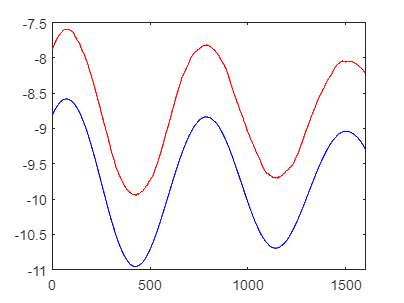

data(i,:)=smoothdata(data(i,:),'sgolay',200);
plot(data(i,:));
hold on;
plot(data_nfree(i,:),'b');
plot(data(i,:),'r')
hold off;

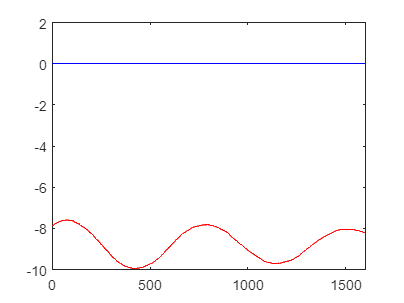


figure(100)
data(7,:)=smoothdata(data(7,:),'gaussian',100000);
plot(data(7,:)-1);
hold on;
plot(data_nfree(7,:),'b');
plot(data(i,:),'r')
hold off;

lowpass(data(8,:),0.5,1e5)%lowpass(x,fpass,fs) x sampled at rate of fs(Hz). fpass is the passband frequency(Hz)

i=6

i =      6


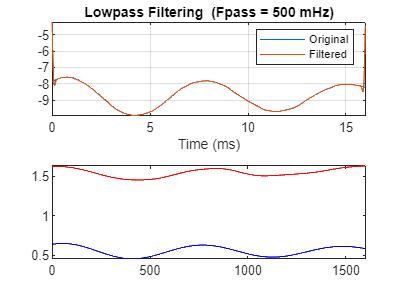

data(6,:)=smoothdata(data(i,:),'gaussian',400);
plot(data(i,:));
hold on;
plot(data_nfree(i,:),'b');
plot(data(i,:),'r')
hold off;


i=5

i =      5


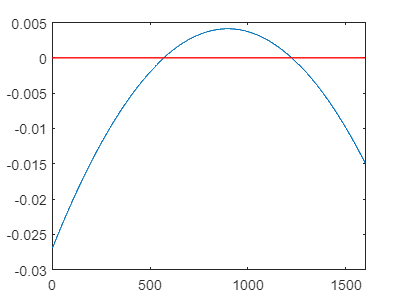

figure(105)
outcheck=smoothdata(data(i,:),'sgolay',10000);
plot(outcheck-1);
hold on;
plot(data_nfree(i,:),'r');

hold off;


i=4

i =      4


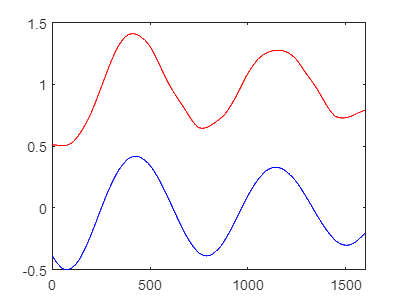

data(i,:)=smoothdata(data(i,:),'gaussian',200);
plot(data(i,:));
hold on;
plot(data_nfree(i,:),'b');
plot(data(i,:),'r')
hold off;


i=3

i =      3


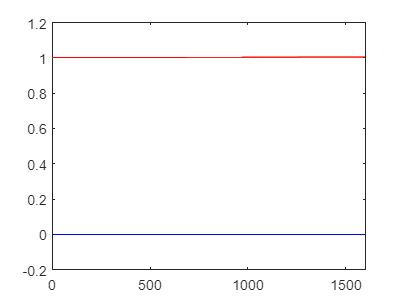

data(i,:)=smoothdata(data(i,:),'gaussian',10000);
plot(data(i,:));
hold on;
plot(data_nfree(i,:),'b');
plot(data(i,:),'r')
hold off;


i=2

i =      2


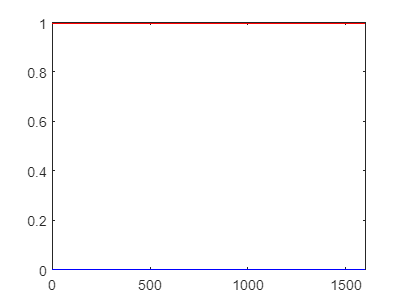

data(i,:)=smoothdata(data(i,:),'gaussian',10000);
plot(data(i,:));
hold on;
plot(data_nfree(i,:),'b');
plot(data(i,:),'r')
hold off;


i=1

i =      1


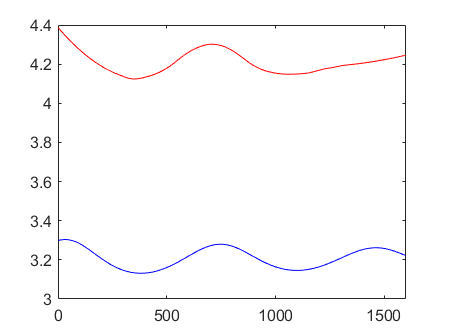

data(i,:)=smoothdata(data(i,:),'loess',600);
plot(data(i,:));
hold on;
plot(data_nfree(i,:),'b');
plot(data(i,:),'r')
hold off;

## Gausian Filter

% winN = [400, 1000,1000,200,1200,400,10000,200,400, 1000,1000,200,1200,400,600,200,400, 1000,1000,200,1200,400,600,200];
% for i = 1:24
%     data(i,:)=smoothdata(data(i,:),'gaussian',winN(i));
% end

## visualise Data

% stackedplot(Data_in');
outputN = 17:24;
inputN = 1:24;

% Dividing the data into train and test
num_step_train = floor(0.9*num_data);
train = data(inputN,1:(num_step_train+1));
test = data(inputN,(num_step_train+1):end);% train last col and test first col is same

## standardise the data for zero mean and unit variance

mu = mean(train,2);
sigma = std(train,0,2);
std_train_data = (train - mu)./sigma;
XTrain = std_train_data(inputN,1:end-1);
YTrain = std_train_data(outputN,2:end);
num_features = size(inputN,2);
num_responses = size(outputN,2);
num_hidden_units = 2304;%200 
layers = [sequenceInputLayer(num_features),lstmLayer(num_hidden_units),fullyConnectedLayer(num_responses),regressionLayer];
layers

layers =   1×4 Layer array with layers:

     1   ''   Sequence Input      Sequence input with 24 dimensions
     2   ''   LSTM                LSTM with 2304 hidden units
     3   ''   Fully Connected     8 fully connected layer
     4   ''   Regression Output   mean-squared-error

options = trainingOptions('adam', 'MaxEpochs',500,'shuffle','never',...
    'GradientThreshold',1,'InitialLearnRate',0.005,...% learn rate changed from 0.005
    'LearnRateSchedule','piecewise','LearnRateDropPeriod',125,...
    'LearnRateDropFactor',0.2,'Verbose',0,'Plots','training-progress');
options

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9
      SquaredGradientDecayFactor: 0.999
                         Epsilon: 1e-08
                InitialLearnRate: 0.005
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2
             LearnRateDropPeriod: 125
                L2Regularization: 0.0001
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 1
                       MaxEpochs: 500
                   MiniBatchSize: 128
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'never'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
      

net = trainNetwork(XTrain,YTrain,layers,options);

%  save('LSTMallnet_3to1.mat') % uncomment when you want to save net trained
% % network

## Load the LSTM network

 load LSTMallnet_3to1.mat


## Prediction on test data

std_test_data = (test - mu)./sigma;% standardise the test data
XTest = std_test_data(inputN ,1:end-1);
% to start prediction we need to net model know the previous training
% points and it will start from that point only, so we first give the
% Xtrain so that it comes on same page as we are to start prediction
net = predictAndUpdateState(net, XTrain);%predictandupdatestate predic and update the trianed network on new data
format long g;
intrstate = std_train_data(inputN,end);% Last(intersection) state of train and test data
[net, YPred] = predictAndUpdateState(net,intrstate); % make first prediction using the last time step of training response : YTrain(end)
YTemp = [intrstate(9:24); YPred]

YTemp = 24×1 single column vector
      0.03635114
        1.359322
        1.050743
      -0.8422211
      -0.6197032
        1.104614
      -0.7419257
       0.8421589
      0.04868942
        1.443919


num_step_test = numel(XTest(1,:));
for i= 2:num_step_test 
    [net,YPred(:,i)] = predictAndUpdateState(net, YTemp(:,(i-1)));
    YTemp = [YTemp, [YTemp(9:24,(i-1));YPred(:,i)]];
end
% Destandardise the test data
YTemp = YTemp.*sigma + mu;
% YPred = YPred.*sigma + mu;
YTest = test(inputN ,2:end);% becz 1st col of test is same as the last col of train
rmse =sqrt(mean((YTemp - YTest).^2));

## Prediction on training data

% std_test_data = (test - mu)./sigma;% standardise the test data
% XTrain = std_test_data(sensorN ,1:end-1);
% XTrain_std = (XTrain - mu)./sigma
XTrain_std= XTrain;
net = predictAndUpdateState(net, XTrain_std);
format long g;
[net, YPred_train] = predictAndUpdateState(net,XTrain_std(:,2)); % make first prediction using the last time step of training response : YTrain(end)
YPred_trainTemp = [XTrain_std(9:24,2);YPred_train];
num_step_train = numel(XTrain_std(1,:));% just for getting no  of time steps
for i= 2:num_step_train
    [net,YPred_train(:,i)] = predictAndUpdateState(net, YPred_trainTemp(:,i-1));
    YPred_trainTemp = [YPred_trainTemp,[YPred_trainTemp(9:24,i-1);YPred_train(:,i)]];
end
% Destandardise the test data
YPred_trainTemp = YPred_trainTemp.*sigma + mu;
YTrain = train(inputN ,2:end);% since we are start prediction after 2nd time step using 1st time step as input
rmse_train =sqrt(mean((YPred_trainTemp - YTrain).^2));

% to save the workspace
% save('worksapce_LSTMall');

% load worksapce_LSTMall.mat

## Plot for prediction on test data

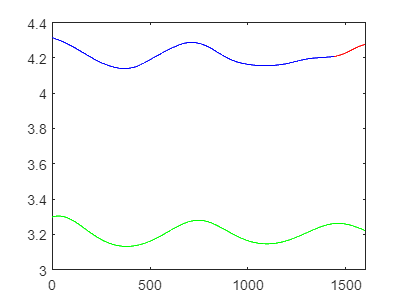

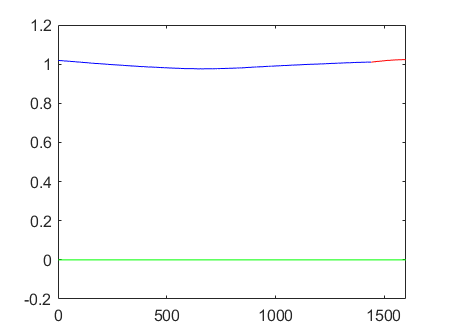

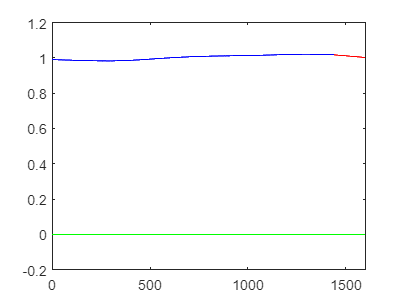

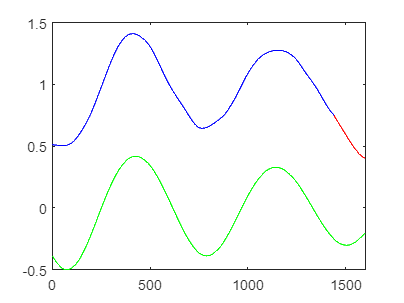

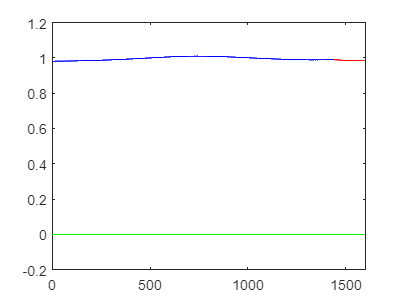

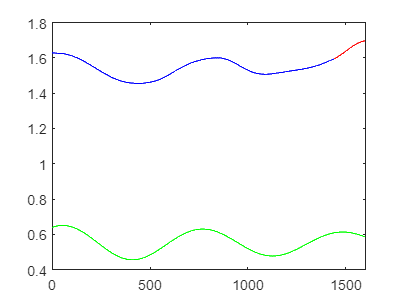

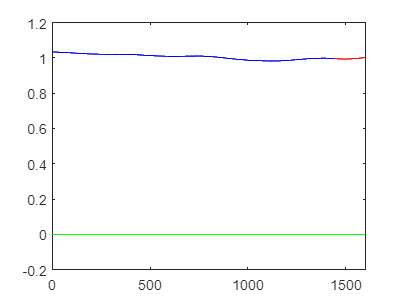

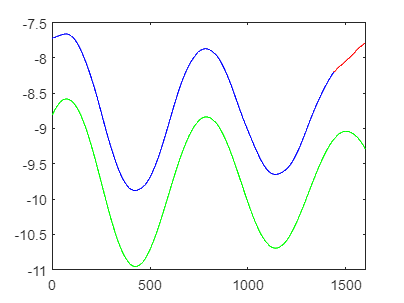

p=0;
for i=1:8

    figure(i);
    plot(train(i,1:end-1)-p,'b');
    hold on
    idx = num_step_train:(num_step_train+num_step_test);
    plot(idx, [data(i,num_step_train)-p,YTemp(i,:)-p],'r')
%     plot(idx, [data(i,num_step_train)-p,YTest(i,:)-p],'b:');
    plot(data_nfree(i,:),'g');
%     legend('train','pred','test','nfree');
    hold off
end

## Plot for prediction on training data

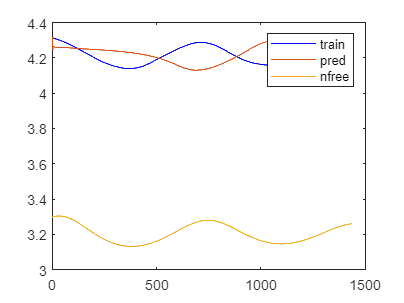

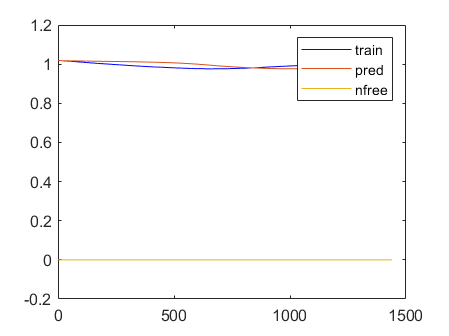

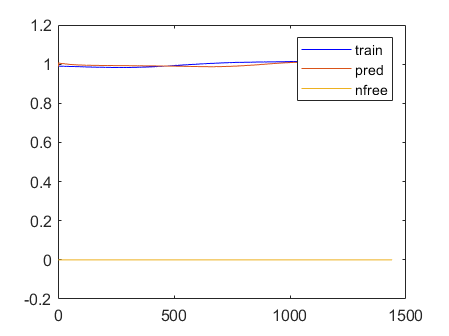

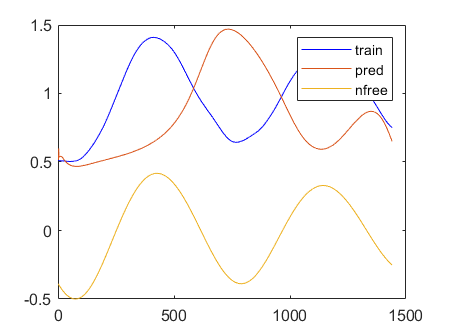

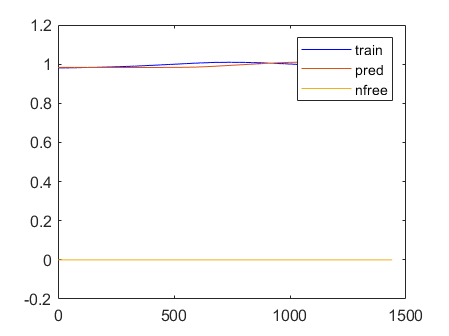

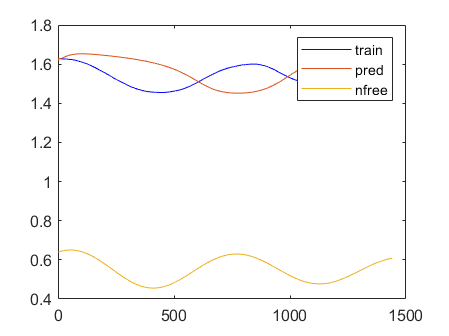

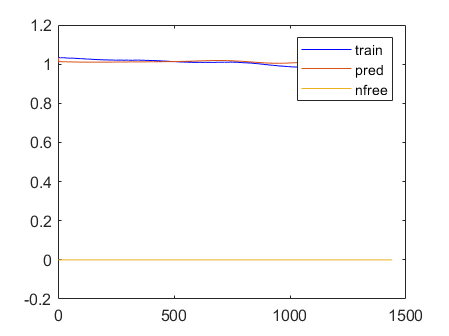

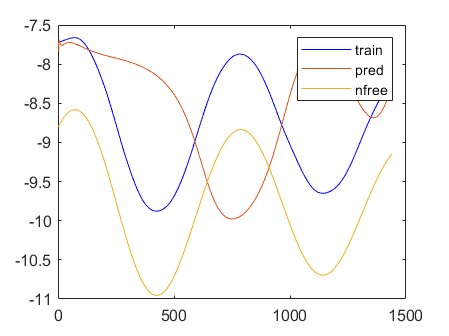

for i=1:8
    figure(i+8);
    plot(train(i,1:end-1)-p,'b');
    hold on;
    plot(YPred_trainTemp(i,:)-p);
    plot(data_nfree(i,1:1440));
    legend('train','pred','nfree');
    hold off
end

% 
